block_width  = 5;
block_height = 5;

x = block_width/2;
y = block_width/2;

res=100

res = 100

t=[];
space_step=0.1;
time_step=0.05;

hold off
sprite = plot(x,y,'O');
block_number=ceil(5/block_height);

hold on 

P_cell_current=0;
P_cell_next=getblock(block_number,block_width,block_height,res);
obj0=line(P_cell_next(:,1),P_cell_next(:,2));

x0=P_cell_next(:,1);
y0=P_cell_next(:,2);

x1=nan

x1 = NaN

y1=6

y1 = 6

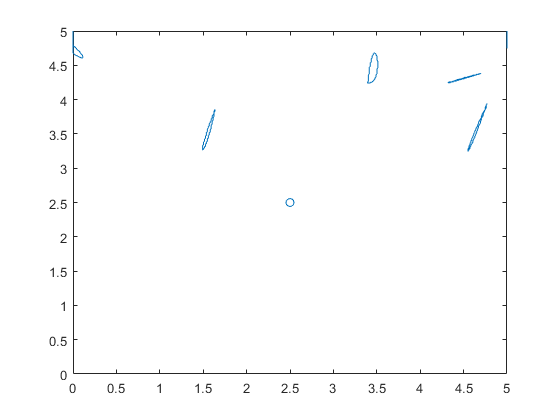


xlim([0 block_width]);
ylim([0 block_width]);


i=0;
app_y=y;


while block_number<30
    tic
    if max(y1)<=0
        block_number=block_number+1;
        P_cell_current=P_cell_next;
        P_cell_next=getblock(block_number,block_width,block_height,res);
        obj1=line(P_cell_next(:,1),P_cell_next(:,2));
        x1=P_cell_next(:,1);
        y1=P_cell_next(:,2);
    elseif max(y0)<=0
        block_number=block_number+1;
        P_cell_current=P_cell_next;
        P_cell_next=getblock(block_number,block_width,block_height,res);
        obj0=line(P_cell_next(:,1),P_cell_next(:,2));
        x0=P_cell_next(:,1);
        y0=P_cell_next(:,2);
    end
    

    app_y=app_y+space_step;
    y1=y1-space_step;
    y0=y0-space_step;

    set(obj0,'XData',[x0],'Ydata',[y0]);
    if ~isnan(x1)
        set(obj1,'XData',[x1],'Ydata',[y1]);
    end

    %set(sprite,'XData',[x],'Ydata',[y]);

%     if rem(round(y,1),1)==0
%         ylim([y-2.5,y+2.5])
%     end
    
    t=[t,toc];
    pause(time_step)
    
end

mean(t)
max(t)